# OFDM algorithm

clc
clear

## parameters setup (802.11a/g)

FFT_size =16;
num_subcar = 16;
num_symbol = 1000;
num_b_per_sym = 16; % For BPSK, equals to num_subcar
guard_interval_ratio = 0.25;
length_cp = FFT_size*guard_interval_ratio; % CP length
m = 2; % mpsk modulation

snr_dB = 0:10;
SNR = 10 %generate desire SNR data

SNR = 10


%====Generating data====
rng(0);
data = randi([0,m-1],1,num_b_per_sym*num_symbol) % size:1*(52*10^4) [0,1]

data =      1     1     0     1     1     0     0     1     1     1     0     1     1     0     1     0     0     1     1     1     1     0     1     1     1     1     1     0     1     0     1     0     0     0     0     1     1     0     1     0     0     0     1     1     0     0     0     1     1     1


## code

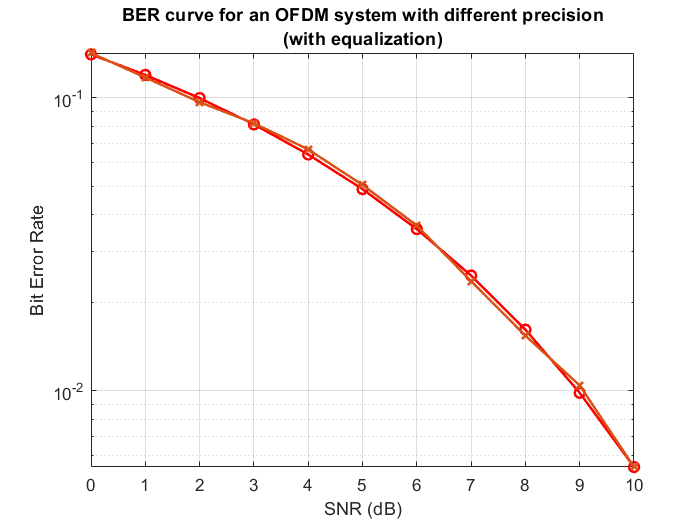

    for ii=1:length(snr_dB)
        %====Transmitter====
        %====BPSK modulation====
        data_mod = pskmod(data,m); % BPSK modulation [-1,1]
        
        %====S/P====
        data_mod = reshape(data_mod,num_b_per_sym,num_symbol).'; % size:(52*10^4)'=10^4*52
        
        %====IFFT====
        data_ifft = sqrt(FFT_size)*ifft(data_mod.',FFT_size).'; % ifft along column
        
        %====Cyclic prefix insertion====
        data_ifft = [data_ifft(:, (FFT_size-length_cp+1):FFT_size ), data_ifft];
        
        %====P/S====
        data_ifft = reshape(data_ifft.', 1, num_symbol*(FFT_size+length_cp)); % data_ifft': 65*10000
        
        %====LTI AWGN channel, Gaussian noise with zreo mean====
        h = [0.8 0.5 0.3 0.1 0.1];
        channel_resp = fft(h,FFT_size);
        
        data_chan = conv(h,data_ifft);
        data_chan = data_chan(1:(FFT_size+length_cp)*num_symbol);
        data_rx = awgn(data_chan,snr_dB(ii),'measured');
        %data_rx = data_chan;
    %% number system changing
        I=imag(data_rx);
        Q=real(data_rx);
        
        i3=3;
        bitwidth=i3-1;
        I_hex=dec2hex(round(I*power(16,bitwidth)),4); %16to2
        Q_hex=dec2hex(round(Q*power(16,bitwidth)),4); %16to2
        
        I_dec2=shex2dec(I_hex)/power(16,bitwidth); %16to2
        Q_dec2=shex2dec(Q_hex)/power(16,bitwidth); %16to2
        
        data_rx=complex(Q_dec2,I_dec2);
    %% save txt file
    if(ii-1==SNR)
        fid=fopen('Ihex.txt','w');%寫入檔案路徑
        [r,c]=size(I_hex);            % 得到矩陣的行數和列數
         for i=1:r
          for j=1:c
          fprintf(fid,'%s',I_hex(i,j));
          end
          fprintf(fid,'\r\n');
         end
        fclose(fid);
        
        fid=fopen('Qhex.txt','w');%寫入檔案路徑
        [r,c]=size(Q_hex);            % 得到矩陣的行數和列數
         for i=1:r
          for j=1:c
          fprintf(fid,'%s',Q_hex(i,j));
          end
          fprintf(fid,'\r\n');
         end
        fclose(fid);
    end
    
    %% receiver
        %====S/P====
        data_rx_p = reshape(data_rx,(FFT_size+length_cp),num_symbol).';
        
        %====Cyclic prefix removal====
        data_rx_p = data_rx_p(:,(length_cp+1):(FFT_size+length_cp));
        
        %====FFT====
        data_fft = 1/sqrt(FFT_size)*fft(data_rx_p.').';
        
        %====Equalizer====
        equal = 1./channel_resp;
        Ie2=imag(equal);
        Qe2=real(equal);
        pres=i3-1;
        
        Ie=dec2hex(round(Ie2*power(16,pres)),4); %16to2
        Qe=dec2hex(round(Qe2*power(16,pres)),4); %16to2
        
        I_dec3=shex2dec(Ie)/power(16,pres); %16to2
        Q_dec3=shex2dec(Qe)/power(16,pres); %16to2
        equal=complex(Q_dec3,I_dec3);
        data_recover = data_fft.*(equal.');
        
        
        %====BPSK demodulation====
        data_demod = pskdemod(data_recover,m);
        data_woeq = pskdemod(data_fft,m);
        
        %====P/S====
        data_demod = reshape(data_demod.',1,num_b_per_sym*num_symbol);
        data_woeq = reshape(data_woeq.',1,num_b_per_sym*num_symbol);
        
        %====save
        if(ii-1==SNR)
           
            fid=fopen('data_demod.txt','w');%寫入檔案路徑
            [r,c]=size(data_demod);            % 得到矩陣的行數和列數
             for i=1:r
              for j=1:c
              fprintf(fid,'%d',data_demod(i,j));
              end
              fprintf(fid,'\r\n');
             end
            fclose(fid);
        end
        %====counting BER====
        [num_ber(ii),ratio_ber(ii)] = biterr(data,data_demod);
        [num_ber2(ii),ratio_ber2(ii)] = biterr(data,data_woeq);
    end
    
    
    snr = 10.^(snr_dB/10);
    subcar_ber = [];
    for i = 1:num_subcar
        temp = qfunc(sqrt(2*snr)*abs(channel_resp(i)));
        subcar_ber = [subcar_ber; temp];
    end
    
    theory_ber = mean(subcar_ber);
    
    figure(1)
        semilogy (snr_dB,theory_ber,'-or','linewidth',1.5);
        hold on;
        semilogy (snr_dB,ratio_ber,'-xb','linewidth',1.5,"ColorMode","auto");
%        hold off;
        grid on
        %legend('Theory','Simulation 0','','Simulation 1',' ','Simulation 2',' ','Simulation 3');
        xlabel('SNR (dB)')
        ylabel('Bit Error Rate')
        title({'BER curve for an OFDM system with different precision';
            '(with equalization)'});

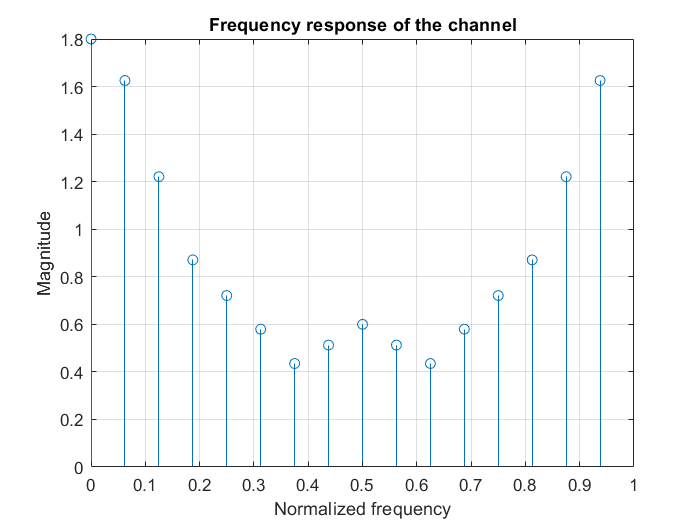

   
    % channel response
    figure(2)
    f_norm = (0:FFT_size-1)/FFT_size;
    stem(f_norm,abs(channel_resp));
    grid on
    xlabel('Normalized frequency')
    ylabel('Magnitude')
    title('Frequency response of the channel');

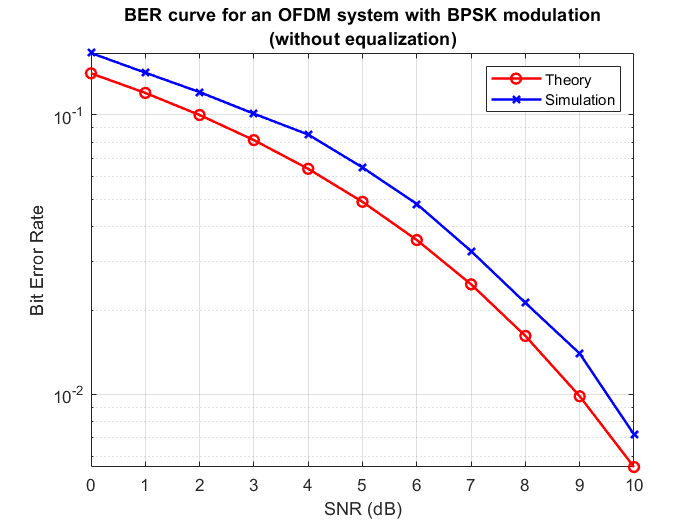

    
    % plotting the result
    figure(3)
    semilogy (snr_dB,theory_ber,'-or','linewidth',1.5);
    hold on;
    semilogy (snr_dB,ratio_ber2,'-xb','linewidth',1.5);
    hold off;
    grid on
    legend('Theory','Simulation');
    xlabel('SNR (dB)')
    ylabel('Bit Error Rate')
    title({'BER curve for an OFDM system with BPSK modulation';
        '(without equalization)'});

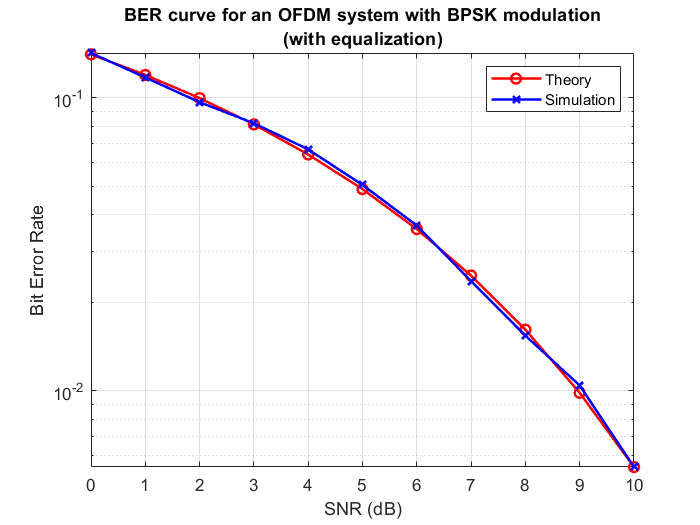

    
    figure(4)
    semilogy (snr_dB,theory_ber,'-or','linewidth',1.5);
    hold on;
    semilogy (snr_dB,ratio_ber,'-xb','linewidth',1.5);
%     diff_max=max(abs(ratio_ber-theory_ber))
%     diff_mean=mean(abs(ratio_ber-theory_ber))
%     diff_min=min(abs(ratio_ber-theory_ber))
    hold off;
    grid on
    legend('Theory','Simulation');
    xlabel('SNR (dB)')
    ylabel('Bit Error Rate')
    title({'BER curve for an OFDM system with BPSK modulation';
        '(with equalization)'});